%计算考虑化学作用后的四锁体系
clear all
syms e r o ;

y1=[];
y2=[];
Plock=[];
Vlock=[];
Vopen=[];

%笼腔长度等于多少个sigma(o)
l=4;

for l = 4:0.1:6
    for k = 0:0.1:2
%计算锁死所占成分
        fun1 = @(x1,x2,x3) P(x3).^(2*k).*P(x2-x3).^(2*k).*P(x1-x2).^(2*k).*P(l-x1).^(k);
        x3max= @(x1,x2) 1*x2;
        x2max= @(x1) 1*x1;
        V_lock = 4*integral3(fun1,0,l,0,x2max,0,x3max);

%计算开放所占成分
        fun2 = @(x1,x2,x3) P(l-x3).^(k).*P(x3).^(k).*P(x2-x3).^(k) ...
            .*P(x1-x2).^(k).*P(l-x1).^(k).*P(x2).^(k).*P(x1-x2).^(k);
        x3max= @(x1,x2) 1*x2;
        x2max= @(x1) 1*x1;
        V_open1 = 2*integral3(fun2,0,l,0,x2max,0,x3max);
        fun3 = @(x1,x2,x3) P(l-x2).^(k).*P(x3).^(k).*P(x2-x3).^(k) ...
            .*P(x1-x2).^(k).*P(l-x1).^(k).*P(x3).^(k).*P(x1-x3).^(k);
        x3max= @(x1,x2) 1*x2;
        x2max= @(x1) 1*x1;
        V_open2 = 2*integral3(fun3,0,l,0,x2max,0,x3max); 
        V_open=V_open1 + V_open2;
        P_lock = V_lock/(V_lock + V_open) %计算锁死所占比例
        Plock=[Plock,P_lock];
    end
end

P_lock = 0.5000

P_lock = 0.3905

P_lock = 0.3807

P_lock = 0.3739

P_lock = 0.3562

P_lock = 0.3034

P_lock = 0.2548

P_lock = 0.2656

P_lock = 0.2770

P_lock = 0.2849

P_lock = 0.2921

P_lock = 0.2939

P_lock = 0.2914

P_lock = 0.2880

P_lock = 0.2849

P_lock = 0.2829

P_lock = 0.2798

P_lock = 0.2784

P_lock = 0.2780

P_lock = 0.2790

P_lock = 0.2819

P_lock = 0.5000

P_lock = 0.4328

P_lock = 0.4592

P_lock = 0.4906

P_lock = 0.5228

P_lock = 0.5507

P_lock = 0.5639

P_lock = 0.5543

P_lock = 0.5427

P_lock = 0.5710

P_lock = 0.6192

P_lock = 0.6654

P_lock = 0.7048

P_lock = 0.7408

P_lock = 0.7730

P_lock = 0.8007

P_lock = 0.8236

P_lock = 0.8432

P_lock = 0.8606

P_lock = 0.8764

P_lock = 0.8906

P_lock = 0.5000

P_lock = 0.4614

P_lock = 0.5099

P_lock = 0.5632

P_lock = 0.6168

P_lock = 0.6682

P_lock = 0.7150

P_lock = 0.7547

P_lock = 0.7855

P_lock = 0.8061

P_lock = 0.8214

P_lock = 0.8357

P_lock = 0.8580

P_lock = 0.8875

P_lock = 0.9125

P_lock = 0.9320

P_lock = 0.9471

P_lock = 0.9589

P_lock = 0.9677

P_lock = 0.9755

P_lock = 0.9821

P_lock = 0.5000

P_lock = 0.4806

P_lock = 0.5410

P_lock = 0.6051

P_lock = 0.6676

P_lock = 0.7254

P_lock = 0.7769

P_lock = 0.8211

P_lock = 0.8578

P_lock = 0.8873

P_lock = 0.9106

P_lock = 0.9281

P_lock = 0.9407

P_lock = 0.9510

P_lock = 0.9587

P_lock = 0.9658

P_lock = 0.9728

P_lock = 0.9791

P_lock = 0.9845

P_lock = 0.9887

P_lock = 0.9918

P_lock = 0.5000

P_lock = 0.4934

P_lock = 0.5595

P_lock = 0.6279

P_lock = 0.6932

P_lock = 0.7525

P_lock = 0.8039

P_lock = 0.8470

P_lock = 0.8821

P_lock = 0.9100

P_lock = 0.9318

P_lock = 0.9484

P_lock = 0.9610

P_lock = 0.9705

P_lock = 0.9775

P_lock = 0.9828

P_lock = 0.9867

P_lock = 0.9897

P_lock = 0.9920

P_lock = 0.9937

P_lock = 0.9951

P_lock = 0.5000

P_lock = 0.5020

P_lock = 0.5699

P_lock = 0.6391

P_lock = 0.7045

P_lock = 0.7632

P_lock = 0.8137

P_lock = 0.8557

P_lock = 0.8897

P_lock = 0.9165

P_lock = 0.9372

P_lock = 0.9531

P_lock = 0.9651

P_lock = 0.9741

P_lock = 0.9808

P_lock = 0.9857

P_lock = 0.9894

P_lock = 0.9922

P_lock = 0.9942

P_lock = 0.9956

P_lock = 0.9967

P_lock = 0.5000

P_lock = 0.5077

P_lock = 0.5754

P_lock = 0.6434

P_lock = 0.7074

P_lock = 0.7648

P_lock = 0.8143

P_lock = 0.8555

P_lock = 0.8890

P_lock = 0.9155

P_lock = 0.9362

P_lock = 0.9521

P_lock = 0.9642

P_lock = 0.9734

P_lock = 0.9802

P_lock = 0.9853

P_lock = 0.9891

P_lock = 0.9919

P_lock = 0.9940

P_lock = 0.9956

P_lock = 0.9967

P_lock = 0.5000

P_lock = 0.5116

P_lock = 0.5777

P_lock = 0.6437

P_lock = 0.7056

P_lock = 0.7614

P_lock = 0.8097

P_lock = 0.8504

P_lock = 0.8837

P_lock = 0.9105

P_lock = 0.9316

P_lock = 0.9481

P_lock = 0.9608

P_lock = 0.9704

P_lock = 0.9778

P_lock = 0.9833

P_lock = 0.9875

P_lock = 0.9907

P_lock = 0.9930

P_lock = 0.9948

P_lock = 0.9961

P_lock = 0.5000

P_lock = 0.5143

P_lock = 0.5782

P_lock = 0.6417

P_lock = 0.7013

P_lock = 0.7553

P_lock = 0.8025

P_lock = 0.8426

P_lock = 0.8760

P_lock = 0.9032

P_lock = 0.9250

P_lock = 0.9422

P_lock = 0.9557

P_lock = 0.9661

P_lock = 0.9742

P_lock = 0.9804

P_lock = 0.9887

P_lock = 0.9915

P_lock = 0.9935

P_lock = 0.9951

P_lock = 0.5000

P_lock = 0.5160

P_lock = 0.5776

P_lock = 0.6384

P_lock = 0.6957

P_lock = 0.7479

P_lock = 0.7940

P_lock = 0.8336

P_lock = 0.8670

P_lock = 0.8947

P_lock = 0.9172

P_lock = 0.9353

P_lock = 0.9496

P_lock = 0.9610

P_lock = 0.9699

P_lock = 0.9768

P_lock = 0.9822

P_lock = 0.9863

P_lock = 0.9895

P_lock = 0.9920

P_lock = 0.9939

P_lock = 0.5000

P_lock = 0.5172

P_lock = 0.5764

P_lock = 0.6347

P_lock = 0.6897

P_lock = 0.7401

P_lock = 0.7851

P_lock = 0.8243

P_lock = 0.8578

P_lock = 0.8859

P_lock = 0.9091

P_lock = 0.9280

P_lock = 0.9433

P_lock = 0.9556

P_lock = 0.9653

P_lock = 0.9730

P_lock = 0.9791

P_lock = 0.9838

P_lock = 0.9875

P_lock = 0.9903

P_lock = 0.9926

P_lock = 0.5000

P_lock = 0.5180

P_lock = 0.5748

P_lock = 0.6307

P_lock = 0.6837

P_lock = 0.7325

P_lock = 0.7765

P_lock = 0.8153

P_lock = 0.8488

P_lock = 0.8773

P_lock = 0.9012

P_lock = 0.9210

P_lock = 0.9372

P_lock = 0.9504

P_lock = 0.9609

P_lock = 0.9694

P_lock = 0.9761

P_lock = 0.9814

P_lock = 0.9856

P_lock = 0.9888

P_lock = 0.9914

P_lock = 0.5000

P_lock = 0.5184

P_lock = 0.5731

P_lock = 0.6267

P_lock = 0.6778

P_lock = 0.7253

P_lock = 0.7684

P_lock = 0.8068

P_lock = 0.8404

P_lock = 0.8694

P_lock = 0.8939

P_lock = 0.9145

P_lock = 0.9316

P_lock = 0.9456

P_lock = 0.9570

P_lock = 0.9661

P_lock = 0.9735

P_lock = 0.9793

P_lock = 0.9839

P_lock = 0.9876

P_lock = 0.9904

P_lock = 0.5000

P_lock = 0.5187

P_lock = 0.5712

P_lock = 0.6229

P_lock = 0.6723

P_lock = 0.7185

P_lock = 0.7608

P_lock = 0.7990

P_lock = 0.8327

P_lock = 0.8621

P_lock = 0.8873

P_lock = 0.9087

P_lock = 0.9266

P_lock = 0.9414

P_lock = 0.9535

P_lock = 0.9634

P_lock = 0.9713

P_lock = 0.9776

P_lock = 0.9827

P_lock = 0.9866

P_lock = 0.9897

P_lock = 0.5000

P_lock = 0.5188

P_lock = 0.5694

P_lock = 0.6193

P_lock = 0.6671

P_lock = 0.7122

P_lock = 0.7539

P_lock = 0.7918

P_lock = 0.8257

P_lock = 0.8555

P_lock = 0.8813

P_lock = 0.9035

P_lock = 0.9221

P_lock = 0.9377

P_lock = 0.9506

P_lock = 0.9610

P_lock = 0.9695

P_lock = 0.9763

P_lock = 0.9817

P_lock = 0.9859

P_lock = 0.9892

P_lock = 0.5000

P_lock = 0.5188

P_lock = 0.5676

P_lock = 0.6158

P_lock = 0.6623

P_lock = 0.7064

P_lock = 0.7475

P_lock = 0.7853

P_lock = 0.8193

P_lock = 0.8495

P_lock = 0.8760

P_lock = 0.8988

P_lock = 0.9183

P_lock = 0.9346

P_lock = 0.9481

P_lock = 0.9591

P_lock = 0.9680

P_lock = 0.9752

P_lock = 0.9809

P_lock = 0.9853

P_lock = 0.9888

P_lock = 0.5000

P_lock = 0.5187

P_lock = 0.5659

P_lock = 0.6126

P_lock = 0.6578

P_lock = 0.7011

P_lock = 0.7417

P_lock = 0.7793

P_lock = 0.8135

P_lock = 0.8442

P_lock = 0.8712

P_lock = 0.8947

P_lock = 0.9148

P_lock = 0.9318

P_lock = 0.9459

P_lock = 0.9575

P_lock = 0.9668

P_lock = 0.9743

P_lock = 0.9802

P_lock = 0.9849

P_lock = 0.9885

P_lock = 0.5000

P_lock = 0.5186

P_lock = 0.5642

P_lock = 0.6095

P_lock = 0.6537

P_lock = 0.6961

P_lock = 0.7363

P_lock = 0.7738

P_lock = 0.8082

P_lock = 0.8393

P_lock = 0.8669

P_lock = 0.8910

P_lock = 0.9118

P_lock = 0.9293

P_lock = 0.9440

P_lock = 0.9560

P_lock = 0.9658

P_lock = 0.9736

P_lock = 0.9797

P_lock = 0.9845

P_lock = 0.9883

P_lock = 0.5000

P_lock = 0.5184

P_lock = 0.5626

P_lock = 0.6066

P_lock = 0.6498

P_lock = 0.6916

P_lock = 0.7314

P_lock = 0.7688

P_lock = 0.8033

P_lock = 0.8348

P_lock = 0.8629

P_lock = 0.8876

P_lock = 0.9090

P_lock = 0.9271

P_lock = 0.9423

P_lock = 0.9547

P_lock = 0.9648

P_lock = 0.9729

P_lock = 0.9793

P_lock = 0.9842

P_lock = 0.9881

P_lock = 0.5000

P_lock = 0.5182

P_lock = 0.5611

P_lock = 0.6039

P_lock = 0.6462

P_lock = 0.6873

P_lock = 0.7267

P_lock = 0.7641

P_lock = 0.7988

P_lock = 0.8306

P_lock = 0.8592

P_lock = 0.8845

P_lock = 0.9064

P_lock = 0.9251

P_lock = 0.9407

P_lock = 0.9536

P_lock = 0.9640

P_lock = 0.9723

P_lock = 0.9788

P_lock = 0.9839

P_lock = 0.9879

P_lock = 0.5000

P_lock = 0.5180

P_lock = 0.5596

P_lock = 0.6014

P_lock = 0.6428

P_lock = 0.6833

P_lock = 0.7224

P_lock = 0.7597

P_lock = 0.7946

P_lock = 0.8267

P_lock = 0.8558

P_lock = 0.8816

P_lock = 0.9040

P_lock = 0.9232

P_lock = 0.9392

P_lock = 0.9525

P_lock = 0.9632

P_lock = 0.9717

P_lock = 0.9784

P_lock = 0.9837

P_lock = 0.9877



l=4:0.1:6;
k=0:400:8000;
[L,K]=meshgrid(l,k);
Z=reshape(Plock,[21 21])

Z =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.3905    0.4328    0.4614    0.4806    0.4934    0.5020    0.5077    0.5116    0.5143    0.5160    0.5172    0.5180    0.5184    0.5187    0.5188    0.5188    0.5187    0.5186    0.5184    0.5182    0.5180
    0.3807    0.4592    0.5099    0.5410    0.5595    0.5699    0.5754    0.5777    0.5782    0.5776    0.5764    0.5748    0.5731    0.5712    0.5694    0.5676    0.5659    0.5642    0.5626    0.5611    0.5596
    0.3739    0.4906    0.5632    0.6051    0.6279    0.6391    0.6434    0.6437    0.6417    0.6384    0.6347    0.6307    0.6267    0.6229    0.6193    0.6158    0.6126    0.6095    0.6066    0.6039    0.6014
    0.3562    0.5228    0.6168    0.6676    0.6932    0.7045    0.7074    0.7056    0.7013    0.6957    0.6897    0.6837    0.6778    0.6723    0.6671  

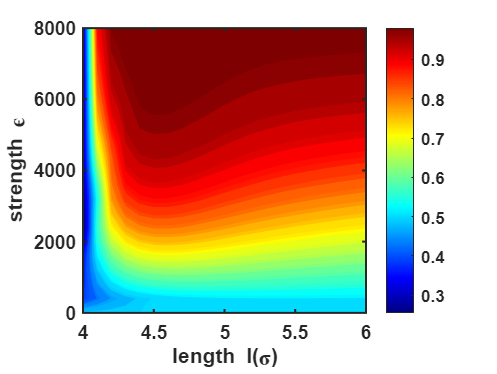

[C,h]=contourf(L,K,Z,50,'--','ShowText','off','LabelSpacing',1000);
h.LevelList=round(h.LevelList,2);  %等高线数值保留小数点后两位
set(h, 'edgecolor','none');
clabel(C,h);

colorbar;
colormap("jet");

set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('length l(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('strength \epsilon','FontName','arial','FontWeight','bold');

function a= E(r) %定义特定的势能函数E(r)
    e=4000;
    o=1;%计算的其实是o/r
    a=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
end

function b=P(r) %定义相应的概率分布函数P(r)
    b=exp(-E(r)/(8.31*298));
end

